# Examen 2020

#### Cuestiones

#### Cuestión 1.

**En una imagen binarizada. ¿Como podríamos seleccionar piezas en forma de cruz (+) de 5x5 píxeles? Razona la respuesta y propón una máscara**

utilizariamos una máscara de 5x5 con la forma del simbolo (+) que al recorrer la imagen con un doble bucle for, cuando coincida la máscara con la forma, nos devolverá la cruz

#### Cuestión 2.

**En una imagen en color ¿Como se realiza la ecualización de histograma para mejorar el contraste? ¿Es diferente el método con respecto a las imágenes en niveles de gris?**

Suponemos imagen RGB, la pasamos al modelo YUV (YCrCb) y ecualizamos la matriz Cr

#### Cuestión 3.

**Una imagen monocroma (16 niveles de gris) de tamaño 10 Kpixeles tiene el histograma siguiente:**

**h(16) = {0,0,0,0,500,100,6000,400,2000,1000,0,0,0,0,0,0}**

**Calcular y representar el histograma ecualizado**

Mal iniciado, este ejercicio se hace de 1 a 16 en lugar de de 0 a 15.

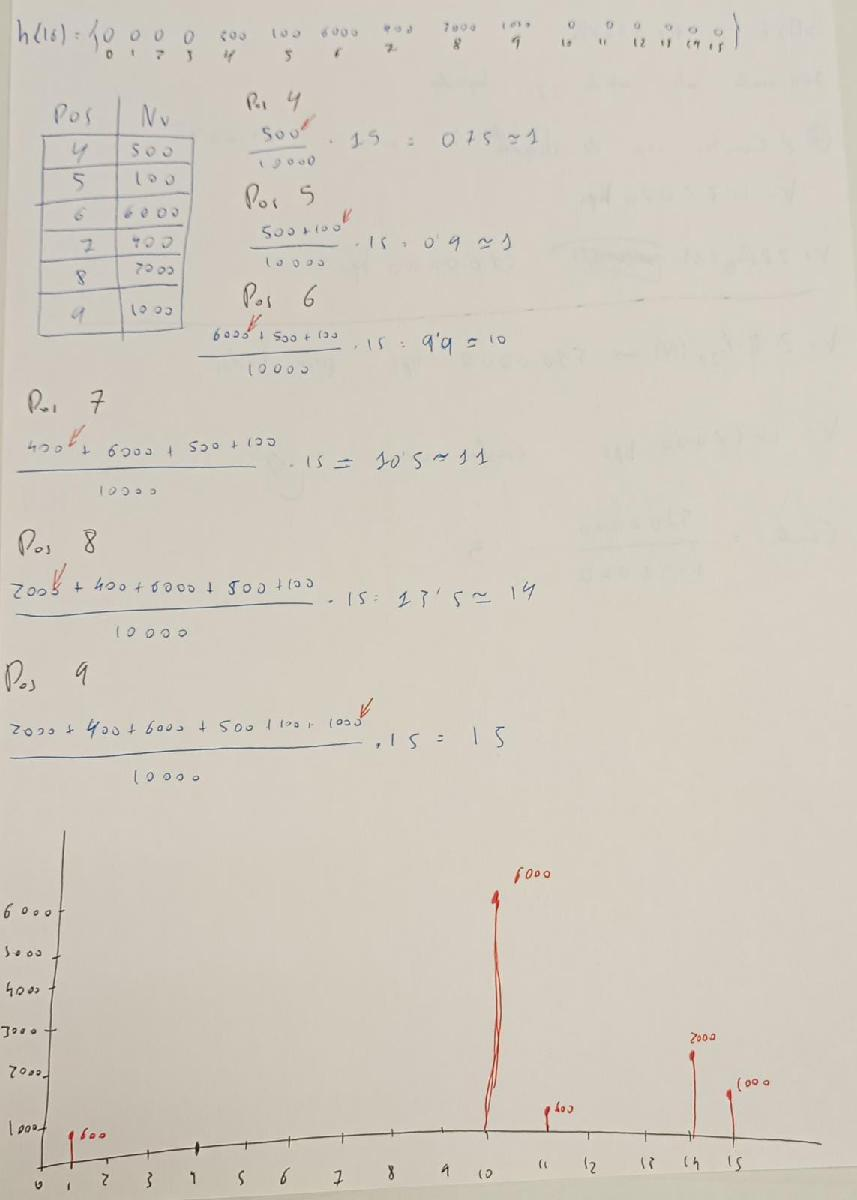

#### Cuestión 4.

**Explica mediante una tabla las diferencias en aplicaciones en TDI entre las técnicas convencionales y la técnica Deep Learning**

TDI Deep Learning

- Clasificación de Imagenes

- Identificación de objetos, rostros, números etc

- Crear imágenes desde cero

TDI Convencional

- Detección de bordes

- Segmentación de color

- Detección de formas geométricas

#### Problema 1.

**Tenemos una imagen (256x256 px) degradada por una interferencia de una frecuencia conocida**

**1) Razona cual sería el mejor procedimiento para eliminar dicho ruido**

Para poder eliminar el ruido de la imagen escogeremos un filtro que trabaje respecto a la frecuencia conocida, en este caso la mejor opción es el Filtro Notch, con el cuál podemos eliminar una frecuencia concreta

**2) Programe un algoritmo en Matlab que aplique la solución descrita anteriormente suponiendo que la interferencia está en la posición (70, 70) de la Transformada de Fourier**

**(Considerar que F = 0 es el centro de la imagen)**

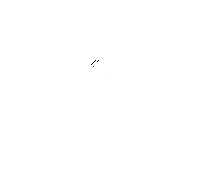

I = imread('cameraman.tif');
I = fftshift(fft2(I));
H = FiltroNotch(256, 256, 15, 2, 70, 70);
GF = H.*I;
G = ifft2(ifftshift(GF));

#### Problema 2.

**Se desea programar un compresor con pérdidas mediante un predictor de 1er orden. El cuantificador debe diseñarse para que la ganancia sea 4 (G = 4)**

**1) Programar el predictor de forma estructurada mediante funciones**

Primero debemos de saber que tenemos una ganancia igual a 4

G = 4;

Para ganar una ganancia de 4 necesitamos que la imagen sea cuatro veces menos pesada

8 bits / 4= 2 bits

Im = imread('');
Im = double(Im);

Obtenemos el nivel máximo de gris

Gris_Max = nextpow2(max(max(Im)));

Al estar utilizando múltiplos de dos necesitamos hacer el logaritmo base 2 del nivel de gris

N = log2(Gris_Max);
N_Nuevo = N / G;

Para obtener Q, el número de escalones de cuantificación necesarios

Q = 2^N_Nuevo;

Necesitamos el tamaño de la imagen

[N, M] = size(Im);

Inicializamos los valores

e = zeros(N, M); %Error
fp = zeros(N, M); %Foto predecida
% ec = zeros(N, M); %Error cuantificado
ec = 0; %Para el apartado b
fc = zeros(N, M); %Imagen cuantificada, será la salida

Inicializaremos el valor del primer pixel

fc(1,1) = Im(1,1);

Calculamos el valor de K, el tamaño del escalón. Comentado para el ejercicio b

% K = Gris_Max/Q;

Calculamos el valor de la primera columna. Empezamos desde 2 porque el primer bit ya está inicializado

for i=2:N

fp es igual a la fc anterior

e es igual  a la imagen que tienes - fp

ec es igual a K*round(e/K)

fc es iguala  fp+ec

    fp(i,1) = fc(i-1, 1);
    e(i,1) = Im(i,1) - fp(i,1);
    ec = error_cuantificado(Q,e(i,j));
    fc(i,1) = fp(i,1) + ec;
end

for i=1:N
    for j=2:M

        fp(i,j) = fc(i, j-1);
        e(i,j) = Im(i,j) - fp(i,j);
        ec = error_cuantificado(Q,e(i,j));
        fc(i,j) = fp(i,j) + ec;

    end
end

**2) Reprogramar únicamente la función de cuantificación para que se pueda introducir un número de estado de cuantificación (Q) variables**

%function ec = error_cuantificado(Q,e)
Gris_Max = 256;
K = Gris_Max/Q;
ec =K*round(e/K);
%end

Creamos la función Filtro Notch

function [H] = FiltroNotch(M, N, D0, n, uk, vk)
H = zeros(M,N);

for  u = 1:M
    for v = 1:N

        Dkn = sqrt((u-N/2-uk)^2 + (v-M/2-vk)^2);
        Dkm = sqrt((u-N/2+uk)^2 + (v-M/2+vk)^2);

        H(u,v) = ((1/(1+((D0/Dkn)^2*n)))*(1/(1+((D0/Dkm)^2*n))));

    end
end

end